## Healthy Systemic Arteries Model


NORMAL Csa = 0.0010 L/mmHg


Systolic= 60.9 mmHg


Diastolic= 38.4 mmHg


Mean= 49.4 mmHg


Pulse= 22.4 mmHg



Task:ARTERIOSCLEROSIS (Csa/2 = 0.0005 L/mmHg)


Systolic= 72.7 mmHg


Diastolic= 28.8 mmHg


Mean= 49.3 mmHg


Pulse= 43.9 mmHg



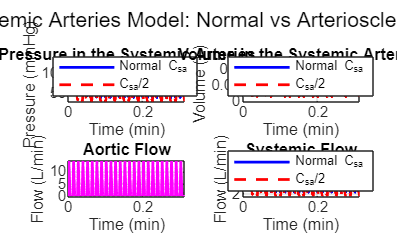

clear;clc;close all 

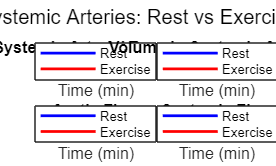


function Q=Qtriangwave(t,Qmax,T,ts,tmax)

% Find remainder of time between one heartbeat (T) and current time (t)
t1=rem(t,T);
    for ii=1:length(t)
        if t1(ii)<=ts % If remainder less than ts, heart is contracting
            if t1(ii)<=tmax % If remainder less than tmax heart is approaching max flow rate
                Q(ii)=Qmax*t1(ii)/tmax;
            else % If remainder greater than tmax but less than ts heart is reducing flow rate
                Q(ii)=Qmax*(ts-t1(ii))/(ts-tmax);
            end
        else % If remainder is not less than ts heart is in diastole, no flow
            Q(ii)=0;
        end
    end
end 

% Initial Parameters + Preallocating

T=0.0125; % Time for 1 heart beat (min) 
ts=0.0050;  % Time for systole (min) 
tmax= 0.002; % Time for max flow rate during systole (min) if using triangle wave 
dt = 1e-6; % Time step (min)
t=0:dt:25*T;  % Vectorized time (min) 

Rs  = 17.5*1.107; % Resistance of the systemic circuit (mmHg/(L/min)) 
Qmax=14.14; % Max flow rate through aorta during systole (L/min) 
Csa = 0.0015*1.2; % Compliance constant for systemic arteries (L/mmHg) 
% Csa & Rs were fiddled with to achieve Psa of 120/80 mmHg 

Psa=zeros(length(t),1); Psa(1)=100; % Pressure in systemic arteries (mmHg)
Vsa=zeros(length(t)-1,1); % Volume in systemic arteries (L)
Qs=zeros(length(t)-1,1); % Systemic Capillaries Flow (L/min)
Qao=zeros(length(t)-1,1); % Systemic Capillaries Flow (L/min)

for k=1:length(t)-1 
    Qao(k)=Qtriangwave(t(k),Qmax,T,ts,tmax);  % Aortic Flow 
    Qs(k)=Psa(k)/Rs; % Systemic Flow, assuming Psv<<Psa
    Psa(k+1)=Psa(k)+dt*(Qao(k)-Qs(k))/Csa;  % Pressure in Systemic Arteries 
    Vsa(k)=Csa*Psa(k); % Volume in Systemic Arteries
end 

% Plotting
figure('Position',[100 100 1000 600]);
sgtitle('Systemic Arteries Model - Triangle Wave for Qao');

subplot(2,2,1);
plot(t,Psa, 'r','LineWidth',1.5);
grid on
xlabel('Time(min)');
ylabel('Pressure (mmHg)');
title('Pressure in the Systemic Arteries');

subplot(2,2,2);
plot(t(1:end-1),Vsa,'b','LineWidth',1.5);
grid on
xlabel('Time(min)');
ylabel('Volume (L)');

CO rest= 2.81 L/min


title('Volume in the Systemic Arteries');

CO exercise= 3.93 L/min


Qmax rest= 14.14 L/min


subplot(2,2,3);

Qmax exer= 19.80 L/min


plot(t(1:end-1),Qao,'m','LineWidth',1.5); 
grid on
xlabel('Time(min)');
ylabel('Flow (L/min)');
title('Aortic Flow');

subplot(2,2,4);
plot(t(1:end-1),Qs,'c','LineWidth',1.5); 
grid on
xlabel('Time(min)');
ylabel('Flow (L/min)');
title('Systemic Flow');

## Question 1: The Aging Cardiovascular System 

- Background: Arteriosclerosis, or "hardening of the arteries," involves a reduction in arterial compliance. This decreased distensibility alters the relationship between blood volume and pressure in the arterial tree. 

- Task: Model arteriosclerosis by reducing the systemic arterial compliance parameter (C_sa) by a factor of 2 from your established baseline Systemic Arterial Model. Analyze and explain the resulting changes in systolic, diastolic, mean, and pulse pressures. 

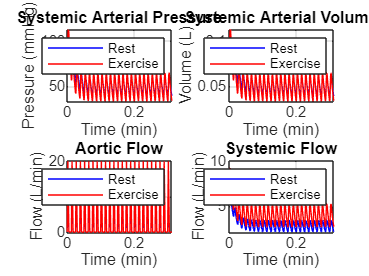

clear;clc;close all 

% Initial Parameters + Preallocating

T=0.0125; % Time for 1 heart beat (min) 
ts=0.0050;  % Time for systole (min) 
tmax= 0.002; % Time for max flow rate during systole (min) if using triangle wave 
dt = 1e-6; % Time step (min)
t=0:dt:25*T;  % Vectorized time (min) 


Rs  = 17.5*1.107; % Resistance of the systemic circuit (mmHg/(L/min)) 
Qmax=14.14; % Max flow rate through aorta during systole (L/min) 
Csa = (0.0015*1.2)/2; % Compliance constant for systemic arteries (L/mmHg) reduced by a factor of 2
% Csa & Rs were fiddled with to achieve Psa of 120/80 mmHg 

Psa=zeros(length(t),1); Psa(1)=100; % Pressure in systemic arteries (mmHg)
Vsa=zeros(length(t)-1,1); % Volume in systemic arteries (L)
Qs=zeros(length(t)-1,1); % Systemic Capillaries Flow (L/min)
Qao=zeros(length(t)-1,1); % Systemic Capillaries Flow (L/min)

for k=1:length(t)-1 
    Qao(k)=Qtriangwave(t(k),Qmax,T,ts,tmax);  % Aortic Flow 
    Qs(k)=Psa(k)/Rs; % Systemic Flow, assuming Psv<<Psa
    Psa(k+1)=Psa(k)+dt*(Qao(k)-Qs(k))/Csa;  % Pressure in Systemic Arteries 
    Vsa(k)=Csa*Psa(k); % Volume in Systemic Arteries
end 

% Plotting
figure('Position',[100 100 1000 600]);
sgtitle('Systemic Arteries Model - Triangle Wave for Qao');

subplot(2,2,1);
plot(t,Psa, 'r','LineWidth',1.5);
grid on
xlabel('Time(min)');
ylabel('Pressure (mmHg)');
title('Pressure in the Systemic Arteries');

subplot(2,2,2);
plot(t(1:end-1),Vsa,'b','LineWidth',1.5);
grid on
xlabel('Time(min)');
ylabel('Volume (L)');
title('Volume in the Systemic Arteries');

subplot(2,2,3);
plot(t(1:end-1),Qao,'m','LineWidth',1.5); 
grid on
xlabel('Time(min)');
ylabel('Flow (L/min)');
title('Aortic Flow');


Stroke volume (tachycardia) = 0.018 L/beat


subplot(2,2,4);
plot(t(1:end-1),Qs,'c','LineWidth',1.5); 
grid on
xlabel('Time(min)');
ylabel('Flow (L/min)');
title('Systemic Flow');


## Question 2: The Normal Hemodynamic Response to Exercise 

- Background: Exercise induces vasodilation in skeletal muscle by reducing systemic vascular resistance (R_s). To maintain blood pressure and increase delivery, cardiac output (CO) must rise, primarily through increased heart rate (HR). 

- Task: Simulate normal exercise using the Systemic Arterial Model. First, reduce R_s by a factor of 2. Then, double the heart rate by halving the cardiac cycle duration (T), systole duration (ts), and time to peak flow (tMAX). To maintain stroke volume (SV), you will need to adjust the peak aortic flow parameter (Qmax). Implement these changes and observe the new waveforms.

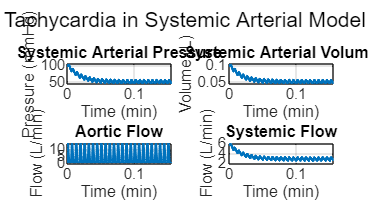

clear;clc;close all 

% Initial Parameters + Preallocating

T=0.0125/2; % Time for 1 heart beat (min) 
ts=0.0050/2;  % Time for systole (min) 
tmax= 0.002/2; % Time for max flow rate during systole (min) if using triangle wave 
dt = 1e-6; % Time step (min)
t=0:dt:25*T;  % Vectorized time (min) 

Rs  = (17.5*1.107)/2 ; % Resistance of the systemic circuit (mmHg/(L/min)) reduced by a factor of 2
Qmax=14.14*2; % Max flow rate through aorta during systole (L/min) 
Csa = 0.0015*1.2; % Compliance constant for systemic arteries (L/mmHg) 
% Csa & Rs were fiddled with to achieve Psa of 120/80 mmHg 

Psa=zeros(length(t),1); Psa(1)=100; % Pressure in systemic arteries (mmHg)
Vsa=zeros(length(t)-1,1); % Volume in systemic arteries (L)
Qs=zeros(length(t)-1,1); % Systemic Capillaries Flow (L/min)
Qao=zeros(length(t)-1,1); % Systemic Capillaries Flow (L/min)

for k=1:length(t)-1 
    Qao(k)=Qtriangwave(t(k),Qmax,T,ts,tmax);  % Aortic Flow 
    Qs(k)=Psa(k)/Rs; % Systemic Flow, assuming Psv<<Psa
    Psa(k+1)=Psa(k)+dt*(Qao(k)-Qs(k))/Csa;  % Pressure in Systemic Arteries 
    Vsa(k)=Csa*Psa(k); % Volume in Systemic Arteries

end 

% Plotting
figure('Position',[100 100 1000 600]);
sgtitle('Systemic Arteries Model - Triangle Wave for Qao');

subplot(2,2,1);
plot(t,Psa, 'r','LineWidth',1.5);
grid on
xlabel('Time(min)');
ylabel('Pressure (mmHg)');
title('Pressure in the Systemic Arteries');

subplot(2,2,2);
plot(t(1:end-1),Vsa,'b','LineWidth',1.5);
grid on
xlabel('Time(min)');
ylabel('Volume (L)');
title('Volume in the Systemic Arteries');

subplot(2,2,3);
plot(t(1:end-1),Qao,'m','LineWidth',1.5); 
grid on
xlabel('Time(min)');
ylabel('Flow (L/min)');
title('Aortic Flow');

subplot(2,2,4);
plot(t(1:end-1),Qs,'c','LineWidth',1.5); 
grid on
xlabel('Time(min)');
ylabel('Flow (L/min)');
title('Systemic Flow');


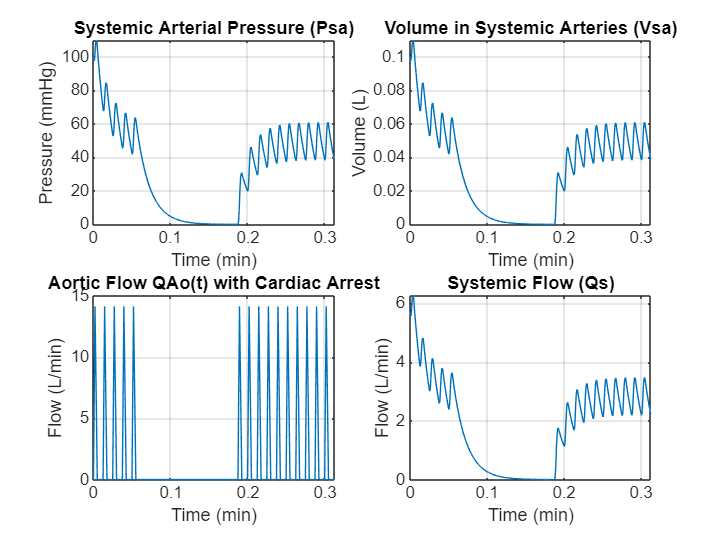

%%%%QUESTION 3%%%%%
%% Systemic Artery Model – Rest vs Exercise (Fixed HR)

clear; clc;

%% Basic heart timing (fixed HR)
T=0.0125; % heart period (min)
ts= 0.005;% systole duration (min)
tmax= 0.002;%time of max flow (min)
dt=0.0001; % time step (min)
t= 0:dt:25*T;% to simulate 25 beats
t_flow= t(1:end-1);

%% Systemic arteries
Csa=0.001;% L/mmHg
Psa0=100; % initial pressure (mmHg)

%% REST
Rs_rest=17.5; % systemic resistance at rest
Qmax_rest =14.14;  % max aortic flow at rest

Psa_rest= zeros(size(t)); 
Psa_rest(1)= Psa0;
QAo_rest=zeros(size(t_flow));

for k = 1:length(t_flow)
    QAo_rest(k)= Qtriangwave(t_flow(k),Qmax_rest,T,ts,tmax);
    Psa_rest(k+1)= Psa_rest(k) + dt*(QAo_rest(k) - Psa_rest(k)/Rs_rest)/Csa;

end

Qs_rest=Psa_rest / Rs_rest;
Vsa_rest=Csa * Psa_rest;

% Cardiac output at rest: mean flow over last beat
idx_last=t_flow >= (t_flow(end) - T);
CO_rest=mean(QAo_rest(idx_last));

%% TASK: exercise with abnormal HR (HR does NOT change)
% Same T, ts, tmax (fixed heart rate), but lower Rs and higher Qmax
Rs_ex=0.7 * Rs_rest;% same Rs reduction as Q2
Qmax_ex=2* Qmax_rest*(Rs_ex/Rs_rest); % choose Qmax to double CO

Psa_ex= zeros(size(t));
Psa_ex(1) = Psa0;
QAo_ex= zeros(size(t_flow));

for k = 1:length(t_flow)
    QAo_ex(k)= Qtriangwave(t_flow(k),Qmax_ex,T,ts,tmax);
    Psa_ex(k+1)= Psa_ex(k) + dt*(QAo_ex(k) - Psa_ex(k)/Rs_ex)/Csa;
end

Qs_ex=Psa_ex / Rs_ex;
Vsa_ex=Csa * Psa_ex;

CO_ex =mean(QAo_ex(idx_last));

fprintf('CO rest= %.2f L/min\n',CO_rest);
fprintf('CO exercise= %.2f L/min\n',CO_ex);
fprintf('Qmax rest= %.2f L/min\n',Qmax_rest);
fprintf('Qmax exer= %.2f L/min\n',Qmax_ex);
%% Plots: Rest vs Exercise
figure;
subplot(2,2,1);
plot(t,Psa_rest,'b',t,Psa_ex,'r');
xlabel('Time (min)'); ylabel('Pressure (mmHg)');
title('Systemic Arterial Pressure'); grid on; legend('Rest','Exercise');

subplot(2,2,2);
plot(t,Vsa_rest,'b',t,Vsa_ex,'r');
xlabel('Time (min)'); ylabel('Volume (L)');
title('Systemic Arterial Volume'); grid on; legend('Rest','Exercise');

subplot(2,2,3);
plot(t_flow,QAo_rest,'b',t_flow,QAo_ex,'r');
xlabel('Time (min)'); ylabel('Flow (L/min)');
title('Aortic Flow'); grid on; legend('Rest','Exercise');

subplot(2,2,4);
plot(t,Qs_rest,'b',t,Qs_ex,'r');
xlabel('Time (min)'); ylabel('Flow (L/min)');
title('Systemic Flow'); grid on; legend('Rest','Exercise');

%%%%%%%%%%%QUESTION 4%%%%%%%%%%
clear; clc;

% Base parameters (same as original model)
Psa0=100;  % initial systemic arterial pressure (mmHg)
Rs= 17.5;% systemic resistance (mmHg/(L/min))
Qmax=14.14; % max aortic flow (L/min)
Csa=0.001;% systemic arterial compliance (L/mmHg)
dt= 0.0001;% time step (min)

T0= 0.0125; % original heart period (min)
ts0= 0.005;% original systole duration (min)
tmax0= 0.002;% original time of max flow (min)

% Tachycardia timing parameters reduced by 2 (/2)
T=T0/2;
ts= ts0/2;
tmax= tmax0/2;

% Time vector for 25 beats at faster heart rate
t=0:dt:25*T;

% Preallocate
Psa= zeros(size(t));
Psa(1)= Psa0;
QAo= zeros(size(t));

% Solving the differential equation
for k = 1:length(t)-1
    QAo(k)= Qtriangwave(t(k),Qmax,T,ts,tmax);           % aortic flow
    Psa(k+1) =Psa(k) +dt*(QAo(k)- Psa(k)/Rs)/Csa;       % arterial pressure
end

Qs=Psa/Rs;% systemic flow
Vsa= Csa*Psa;% arterial volume

%Stroke volume (from last beat) 
lastBeatStart= t(end) - T;
idxLast=t >= lastBeatStart;
SV_tachy=trapz(t(idxLast), QAo(idxLast));

fprintf('Stroke volume (tachycardia) = %.3f L/beat\n', SV_tachy);

%Figures
figure('Position',[100 100 900 500]);
sgtitle('Tachycardia in Systemic Arterial Model');

subplot(2,2,1);
plot(t,Psa,'LineWidth',1.5);
grid on;
xlabel('Time (min)');
ylabel('Pressure (mmHg)');
title('Systemic Arterial Pressure');

subplot(2,2,2);
plot(t,Vsa,'LineWidth',1.5);
grid on;
xlabel('Time (min)');
ylabel('Volume (L)');
title('Systemic Arterial Volume');

subplot(2,2,3);
plot(t(1:end-1),QAo(1:end-1),'LineWidth',1.5);
grid on;
xlabel('Time (min)');
ylabel('Flow (L/min)');
title('Aortic Flow');

subplot(2,2,4);
plot(t,Qs,'LineWidth',1.5);
grid on;
xlabel('Time (min)');
ylabel('Flow (L/min)');
title('Systemic Flow');


%%%%%%%question 5%%%%%%%%%%
%Same parameters
Psa0= 100;% initial systemic arterial pressure (mmHg)
Rs= 17.5;% systemic resistance (mmHg/(L/min))
Csa= 0.001;% systemic arterial compliance (L/mmHg)
T=0.0125;% heart period (min)
ts=0.005;% systole duration (min)
tmax =0.002;% time of max flow (min)
Qmax =14.14;% max aortic flow (L/min)

dt=0.0001;% time step (min)
t=0:dt:25*T;% 25 beats

% choose arrest and restart times (in minutes)
t_arrest= 5*T;% cardiac arrest starts after 5 beats
t_restart=15*T;% and ends after 15 beats

%% Starting
Psa=zeros(size(t));   Psa(1) = Psa0;
QAo= zeros(size(t));
Vsa=zeros(size(t));
Qs= zeros(size(t));

% Solving DFQ
for k= 1:length(t)-1
    
    % normal aortic flow from LV (triangle wave)
    Q_normal =Qtriangwave(t(k),Qmax,T,ts,tmax);
    
    % cardiac arrest: no outflow between t_arrest and t_restart
    if t(k) >= t_arrest && t(k) <= t_restart
        QAo(k)=0;
    else
        QAo(k)=Q_normal;
    end
    
    % systemic arterial pressure update
    Psa(k+1)=Psa(k) +dt *(QAo(k) -Psa(k)/Rs) /Csa;
end

% derived variables
Qs= Psa / Rs; % systemic flow
Vsa=Csa.* Psa;% systemic arterial volume

%% Figures
figure;

subplot(2,2,1);
plot(t,Psa); grid on
xlabel('Time (min)'); ylabel('Pressure (mmHg)');
title('Systemic Arterial Pressure (Psa)');

subplot(2,2,2);
plot(t,Vsa); grid on
xlabel('Time (min)'); ylabel('Volume (L)');
title('Volume in Systemic Arteries (Vsa)');

subplot(2,2,3);
plot(t(1:end-1),QAo(1:end-1)); grid on
xlabel('Time (min)'); ylabel('Flow (L/min)');
title('Aortic Flow QAo(t) with Cardiac Arrest');

subplot(2,2,4);
plot(t,Qs); grid on
xlabel('Time (min)'); ylabel('Flow (L/min)');
title('Systemic Flow (Qs)');

%% Triangle-wave aortic flow function (same as before)
function Q = Qtriangwave(t,Qmax,T,ts,tmax)
t1 = rem(t,T);
for ii = 1:length(t)
    if t1(ii) <= ts               % systole
        if t1(ii) <= tmax         % upstroke
            Q(ii) = Qmax*t1(ii)/tmax;
        else                      % downstroke
            Q(ii) = Qmax*(ts-t1(ii))/(ts-tmax);
        end
    else                          % diastole
        Q(ii) = 0;
    end
end
end
